# Lab 5

Looking for the standard model Higgs boson from proton-proton collisions at $\sqrt{\;s}=13\mathrm{TeV}$ (how hard the protons hit, observer-independent and the hard limit on the mass of real particles created from collision).

Higgs-jet defined in Section 4 of Atlas Paper. When contransverse momentums greater than 250, eta smaller than 2, and associated b-hadrons from decay, the acceptance rises with increasing transverse momentum.

Do only first 2 probems from higgs data file.

clc; clear all; close all;
% signal dataset is labelled higgs
% background dataset is labeled "qcd"
h5disp("higgs_100000_pt_1000_1200.h5");

HDF5 higgs_100000_pt_1000_1200.h5 
Group '/' 
    Dataset 'higgs_100000_pt_1000_1200' 
        Size:  14x100000
        MaxSize:  14x100000
        Datatype:   H5T_IEEE_F64LE (double)
        ChunkSize:  []
        Filters:  none
        FillValue:  0.000000


h5disp("qcd_100000_pt_1000_1200.h5");

HDF5 qcd_100000_pt_1000_1200.h5 
Group '/' 
    Dataset 'qcd_100000_pt_1000_1200' 
        Size:  14x100000
        MaxSize:  14x100000
        Datatype:   H5T_IEEE_F64LE (double)
        ChunkSize:  []
        Filters:  none
        FillValue:  0.000000



signaldata1 = h5read("higgs_100000_pt_1000_1200.h5",'/higgs_100000_pt_1000_1200');
bgdata1 = h5read("qcd_100000_pt_1000_1200.h5",'/qcd_100000_pt_1000_1200');

signaldata2 = h5read("higgs_100000_pt_250_500.h5",'/higgs_100000_pt_250_500');
bgdata2 = h5read("qcd_100000_pt_250_500.h5",'/qcd_100000_pt_250_500');

Exploring the data. The data labelled 'higgs' represents jets from a Higgs decay. The data labelled 'qcd' represents jets from the QCD (quantum chromodynamics) background. The QCD background are the other particles created by the hadronic jets that make it harder to identify the Higgs.  The samples are representative of a binary classification problem with classes 'higgs' and 'qcd'.

Each row contains a different recorded jet feature, 14 in total. They are: 'pt', 'eta', 'phi', 'mass', 'ee2', 'ee3', 'd2', 'angularity', 't1', 't2', 't3', 't21', 't32', 'KtDeltaR'.

**'pt' **: the 'transverse momentum" of the jet (perpendicular to beam line) in GeV. This data set (1) is a collection of those in the range of 1000 GeV to 1200 GeV. Momentum along beam line (parallel) may be left over from the beam itself. High perpendicular suggests a clean, hard collision, which means the event might be interesting to look at.

Higher tranverse momentum means more likely to be Higgs (with some other conditions also met).

% min(bgdata1(1,:)), min(signaldata1(1,:)), max(bgdata1(1,:)), max(signaldata1(1,:))

**'eta'** : the "pseudorapidity" is a spatial coordinate decribing the angle of a particle relative to the beam axis. This one may describe jet positioning? It has an odd mathematical definition, values range from 0 to 4, with 0 is along beam axis. Negative sign allowed.

(Something on what is considered in Higgs paper of magnitude less than 2? Like with transverse momentum, they chose this range for considering acceptance.)

% min(bgdata1(2,:)), min(signaldata1(2,:)), max(bgdata1(2,:)), max(signaldata1(2,:))

**'phi'** : the "azimuth", another spatial coordinate like pseudorapidity (eta). Panapto lecture slide has this and eta together to plot the coordinates on calorimeter cells.

**'mass'** : Jet mass in GeV. Invariant mass is $E^2 =P^2 +m^2$.

**'ee2'** : 2-point ECF (energy correlation function) ratio $e_2^{\left(\alpha \;\right)}$. (sum of three-pronged jet angles^alpha?)

**'ee3'** : 3-point ECF ratio $e_3^{\left(\beta \;\right)}$. (angle product^beta?)

**'d2'** : 3-to 2-point ECF ratio. (jet shape function, used in tagging?) Seems important. With mass plots in simulated data repository.

(phase space of three energy correlation functions identify family of discriminating variables using power counting arguments)

**'angularity'** :

% 't1' : something to do with subjets? jets are sprays of lighter
% particles. may not be as important to understand in this case. we may be
% just looking at energy? wiki for jet_(particle_physics)
%min(bgdata1(9,:)), max(bgdata1(9,:)), min(signaldata1(9,:)), max(signaldata1(9,:))
% 't2'
%min(bgdata1(10,:)), max(bgdata1(10,:)), min(signaldata1(10,:)), max(signaldata1(10,:))
% 't3',
%min(bgdata1(11,:)), max(bgdata1(11,:)), min(signaldata1(11,:)), max(signaldata1(11,:))
% 't21',
%min(bgdata1(12,:)), max(bgdata1(12,:)), min(signaldata1(12,:)), max(signaldata1(12,:))

**'t32'** : the N-subjettiness observable $\tau {\;}_{3,2}^{\left(\beta \;\right)}$. One of the most effective discriminants for boosted top quarks against the QCD background.

%min(bgdata1(13,:)), max(bgdata1(13,:)), min(signaldata1(13,:)), max(signaldata1(13,:))

% 'KtDeltaR' (kt is a sequential recombination type algorithm) (durham?)

2. a) Discriminating power between signal and background. Higgs mass is expected to be about 125 GeV, other features unclear.

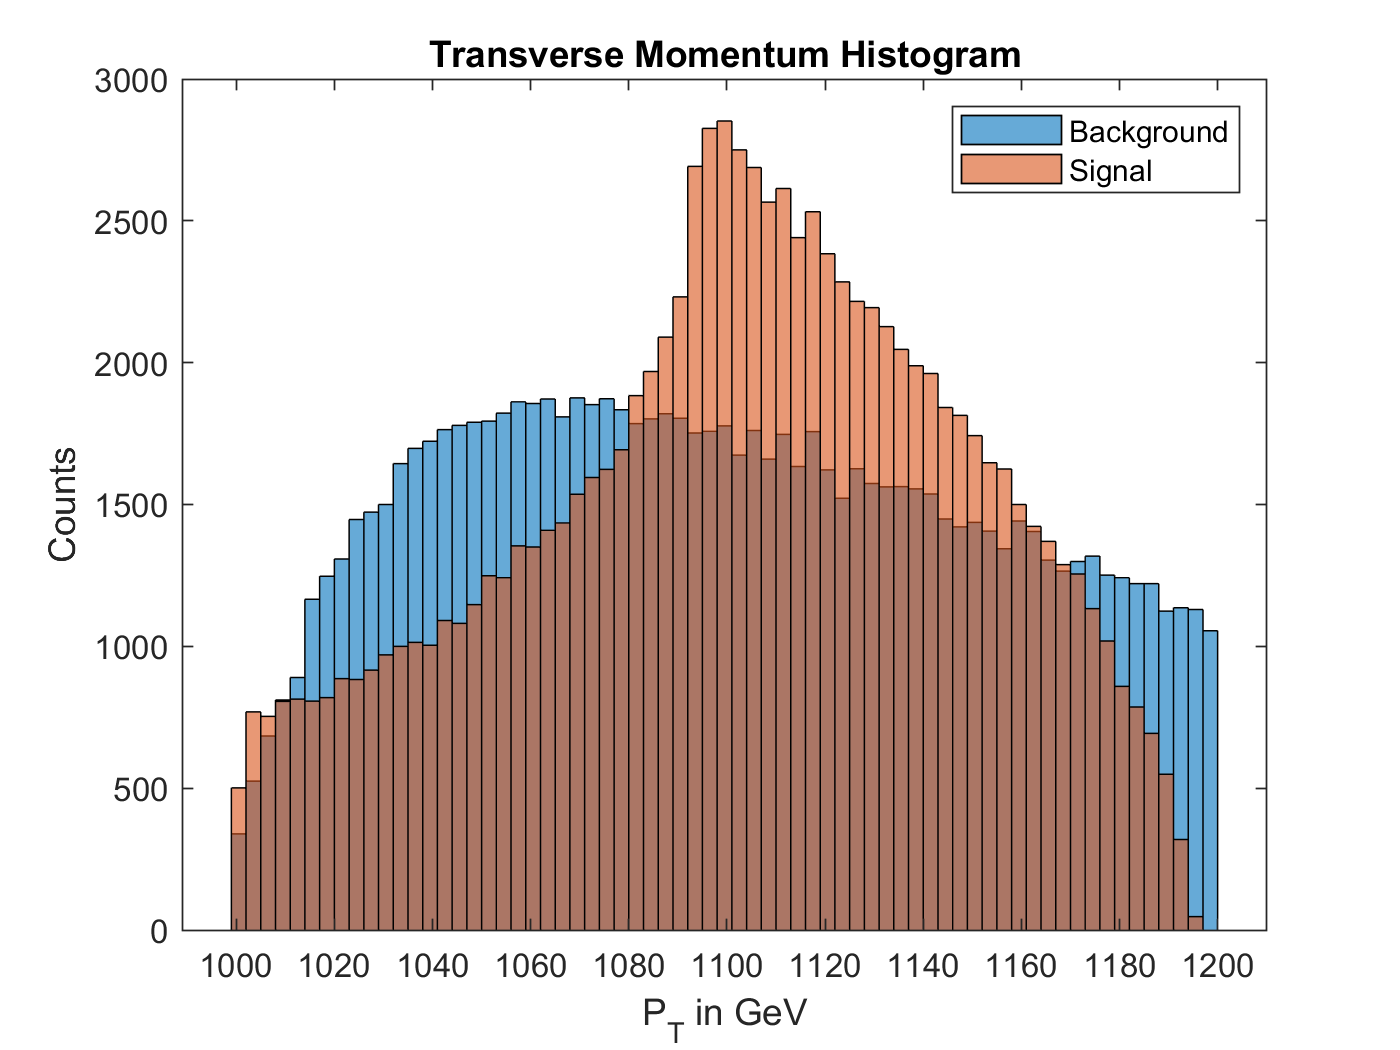

close all;
histogram(bgdata1(1,:)), hold on, histogram(signaldata1(1,:)), title("Transverse Momentum Histogram");
legend("Background","Signal"), xlabel("P_T in GeV"), ylabel("Counts"), hold off;

The histogram distribution of transverse momentum within the 1000-1200 interval. Meaning of shapes unknown.

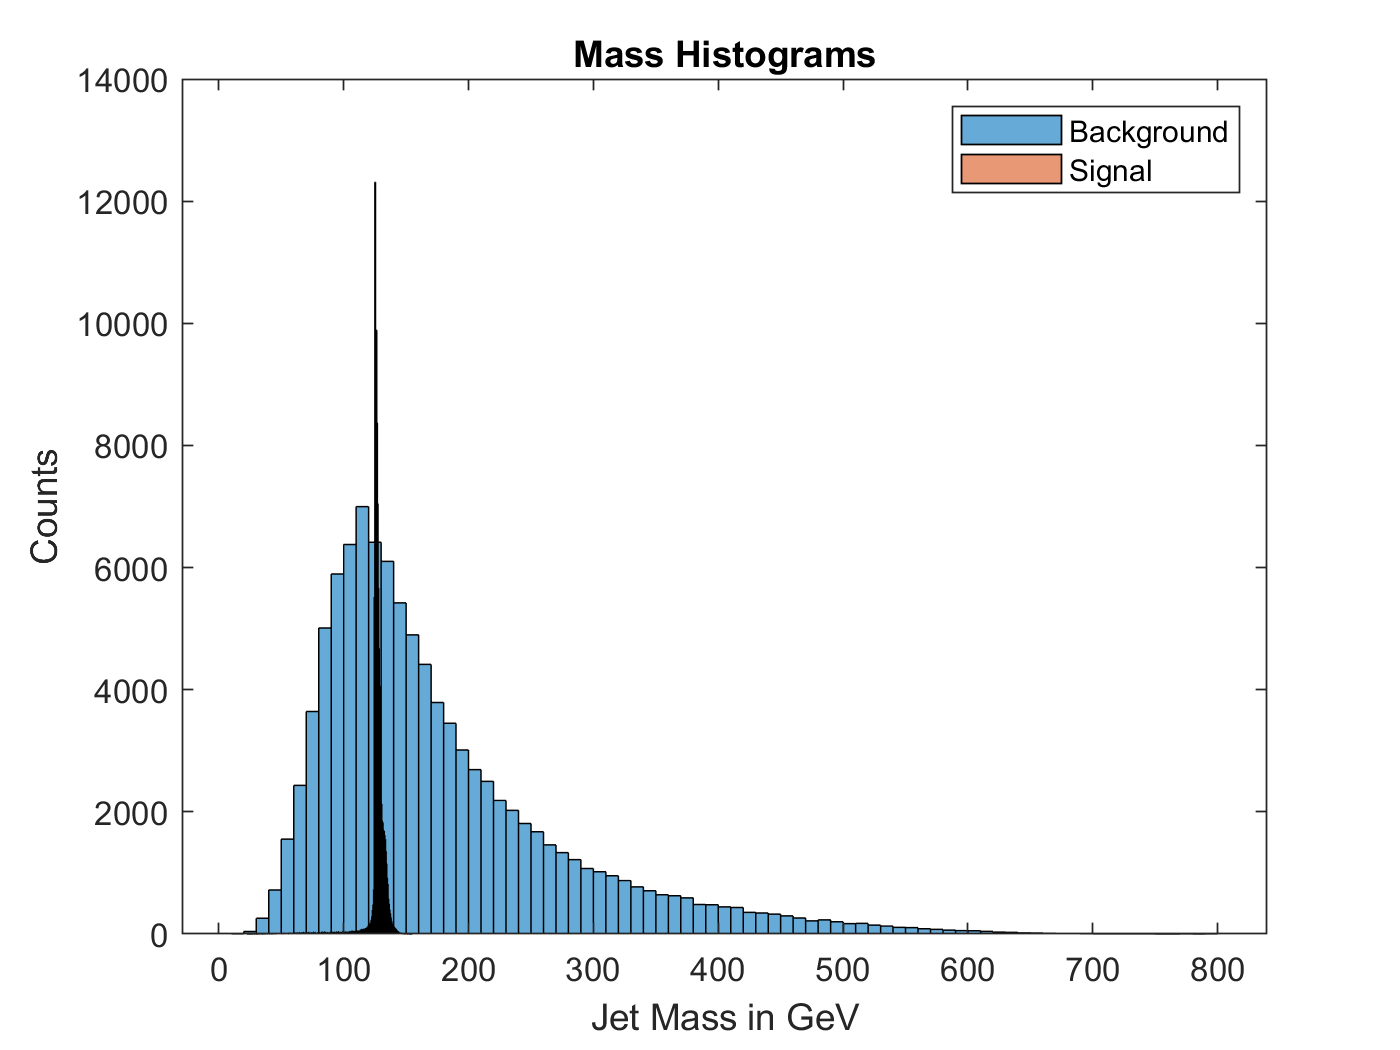

histogram(bgdata1(4,:)), title("Mass Histograms"), ylabel("Counts"), hold on;
histogram(signaldata1(4,:)), legend("Background","Signal"), xlabel("Jet Mass in GeV"), hold off;

Masses of the Higgs jet data are tightly centered at about 125 GeV, which is the expected mass for the Higgs. Background is more spread out and is capable of producing much higher mass jets. Background shape and smoothness suggests it may be following some probability distribution that we can look for.

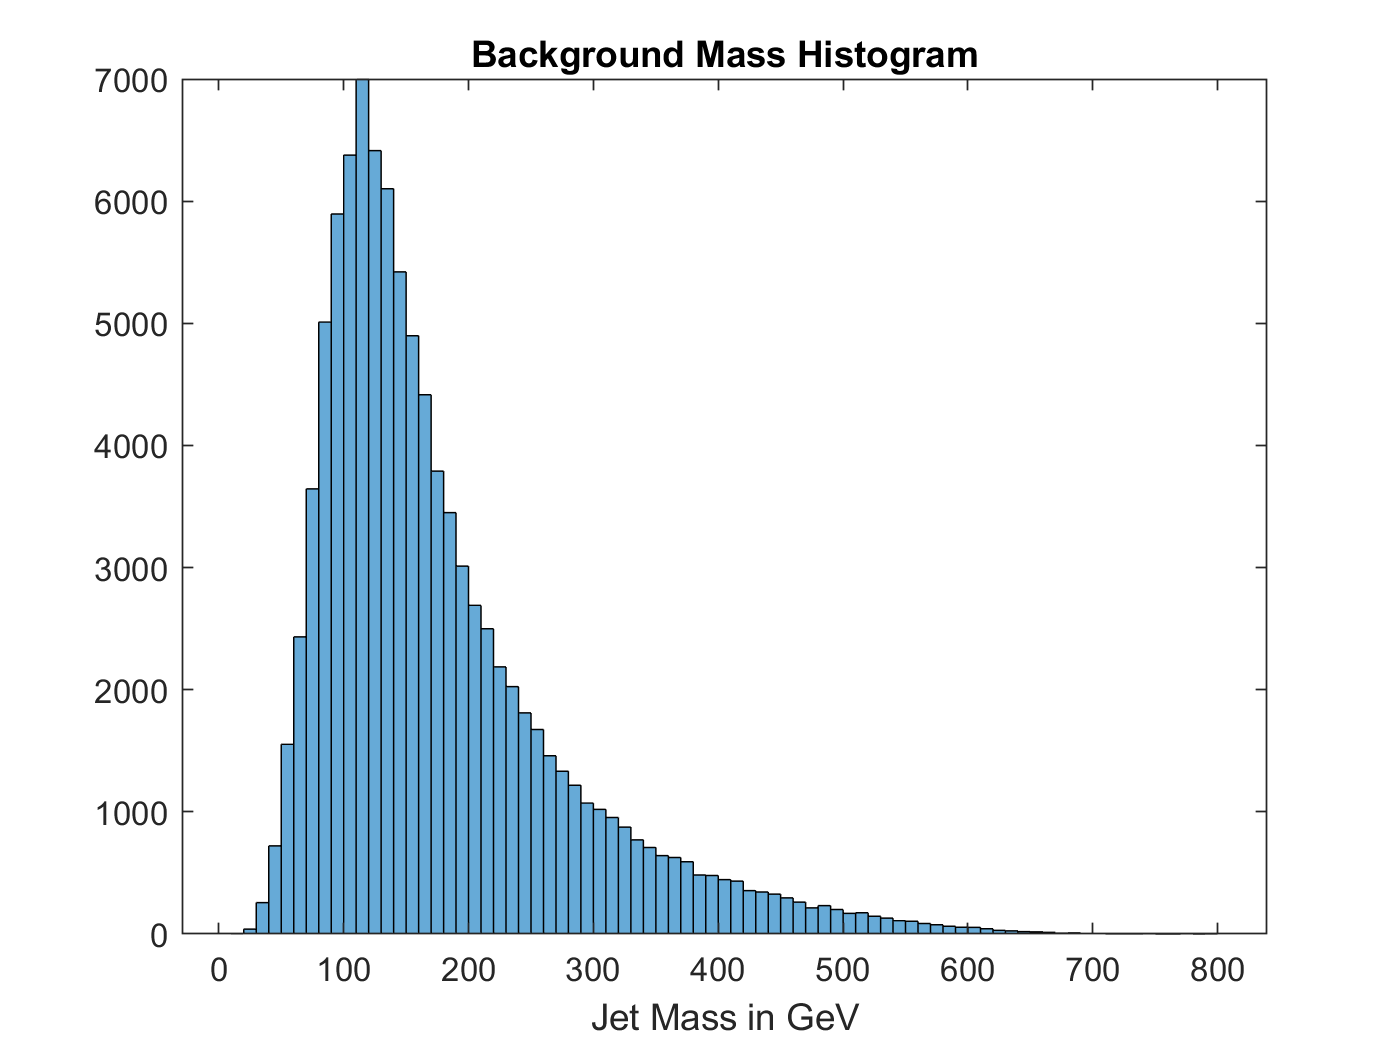

histogram(bgdata1(4,:)), title("Background Mass Histogram"), xlabel("Jet Mass in GeV");

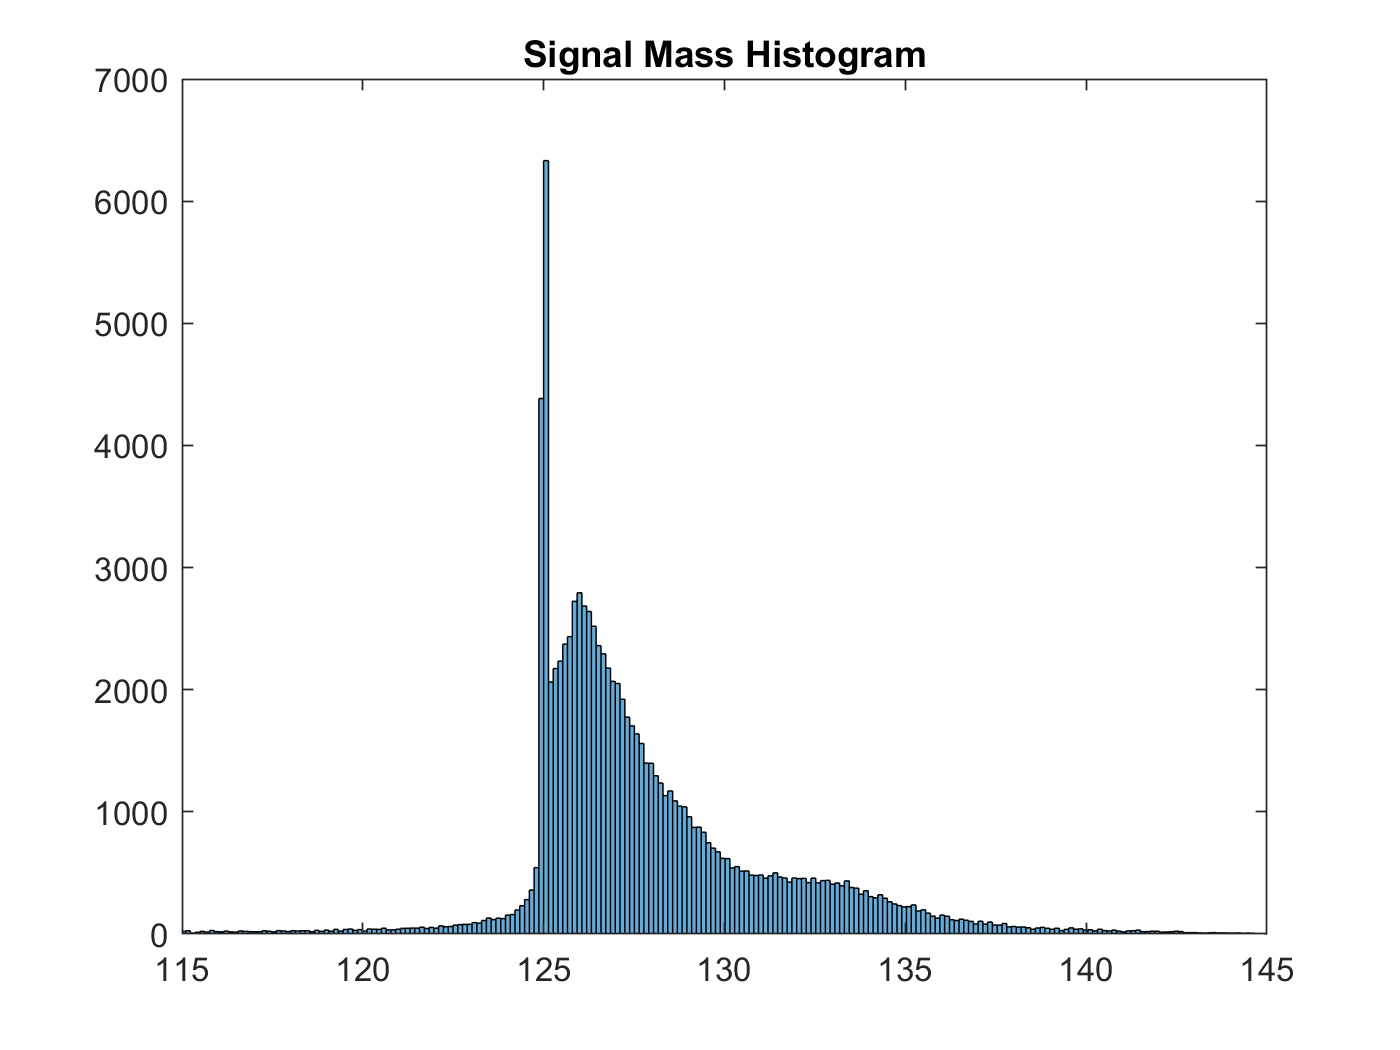

% log of input almost is something, finer binning not revealing new features.
% set(gca,'YScale','log'); % not interesting
histogram(signaldata1(4,:),1000), xlim([115,145]), title("Signal Mass Histogram");

% set(gca,'YScale','log'); % not interesting

Fine histogram bins of the signal show that it is sharply peaked at 125, with a smaller second peak at 126. There is a range of values from 125 to 135 with some trailing edges. PDGLive has the Higgs mass listed as 125.10 +/- 0.14 GeV.

Peak at 126 GeV almost looks like the shape of the background.

The signal peak is present, May just be messy merged data, try variation to pull apart. Force the background shape then see what falls out?

Test plots of locations using pseudorapidity and azimuth. (to do)

% scatter(bgdata1(2,:),bgdata1(3,:));
% scatter(signaldata1(2,:),signaldata1(3,:));

More test plots

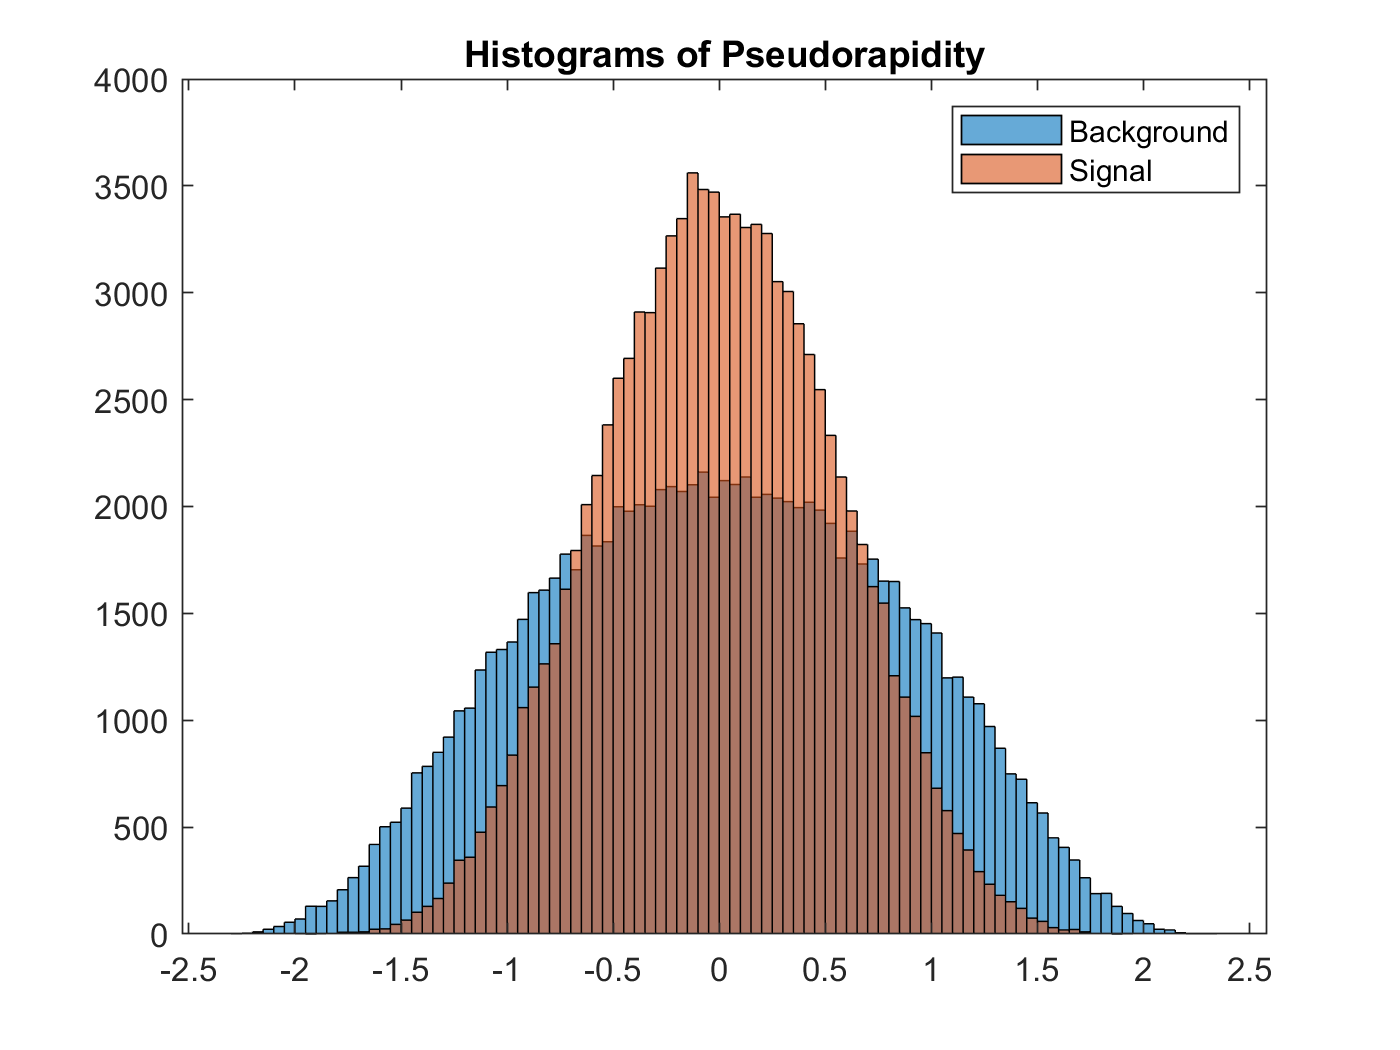

histogram(bgdata1(2,:)), hold on, histogram(signaldata1(2,:)), title("Histograms of Pseudorapidity"), legend("Background","Signal");
hold off;

The pseudorapidity appears Gaussian distributed and centered at 0 (no deflection). The Higgs jet distribution is narrower suggesting a smaller jet angle from the beam.

% histogram(bgdata1(3,:)), hold on, histogram(signaldata1(3,:)), hold off;
% not clear

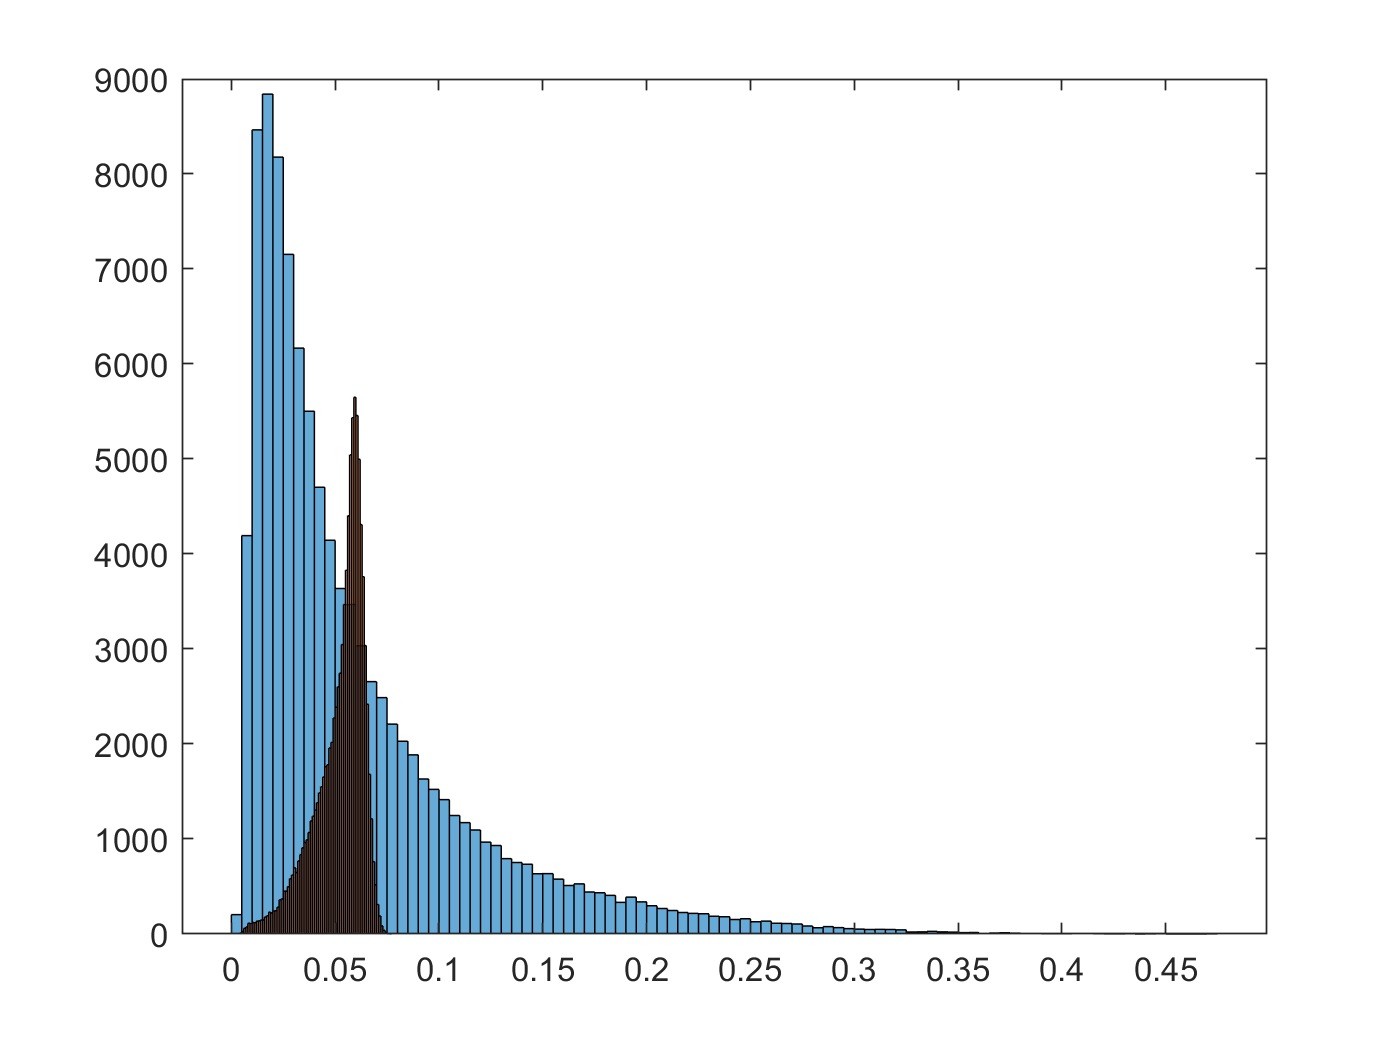

close all hidden;
%subplot(2,2,1);
histogram(bgdata1(5,:)), hold on, histogram(signaldata1(5,:)), hold off;

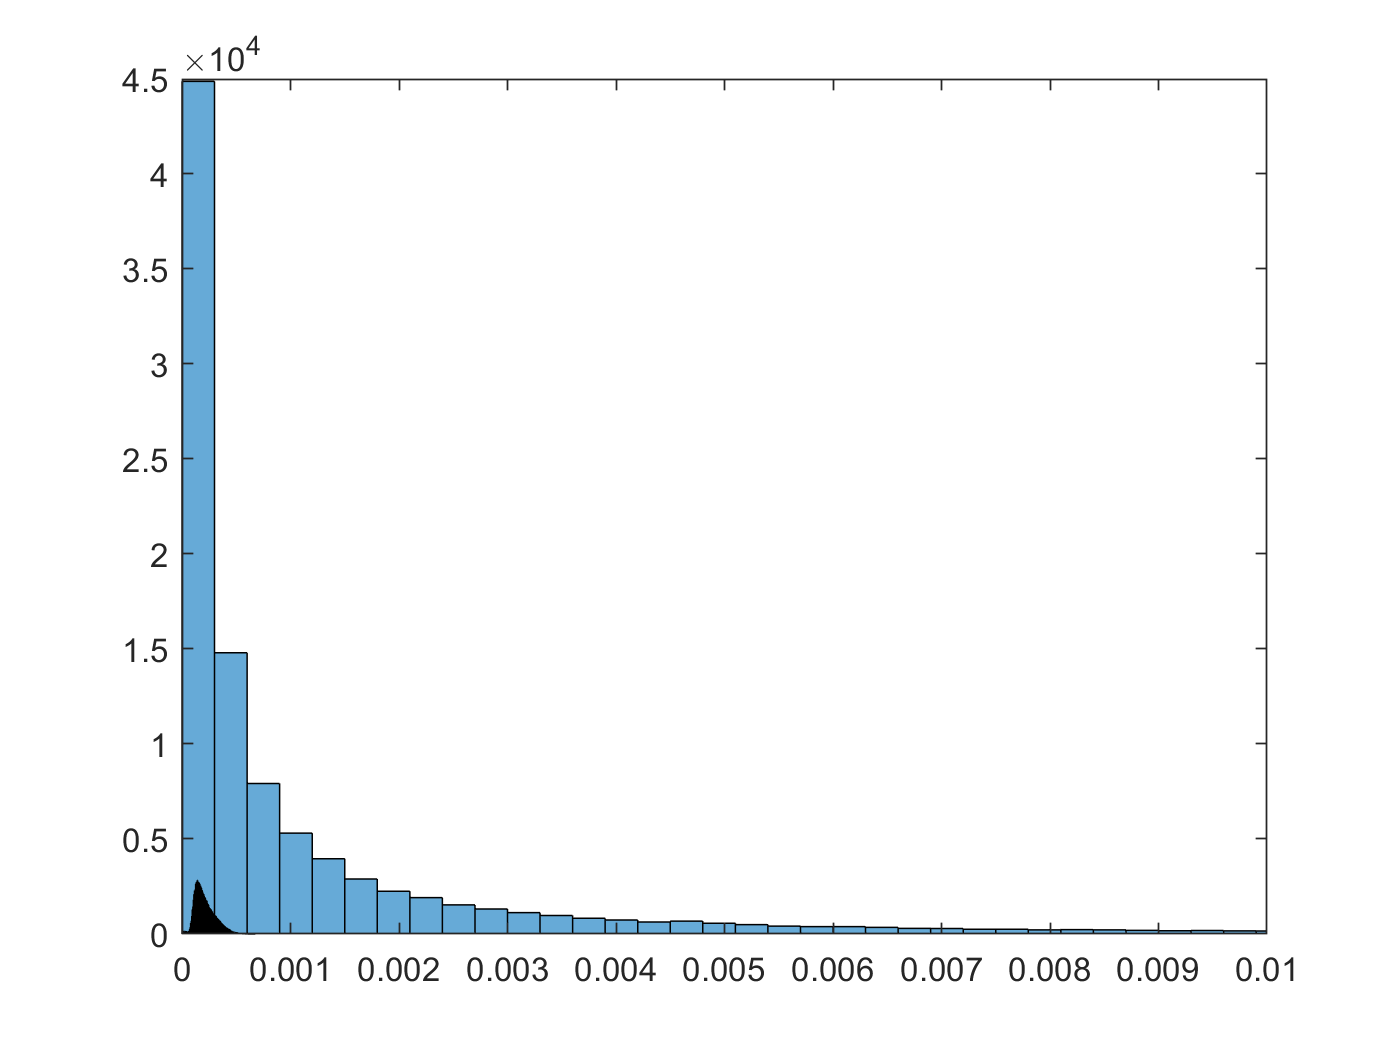

%subplot(2,2,2);
histogram(bgdata1(6,:)), hold on, histogram(signaldata1(6,:)), xlim([0,0.01]), hold off;

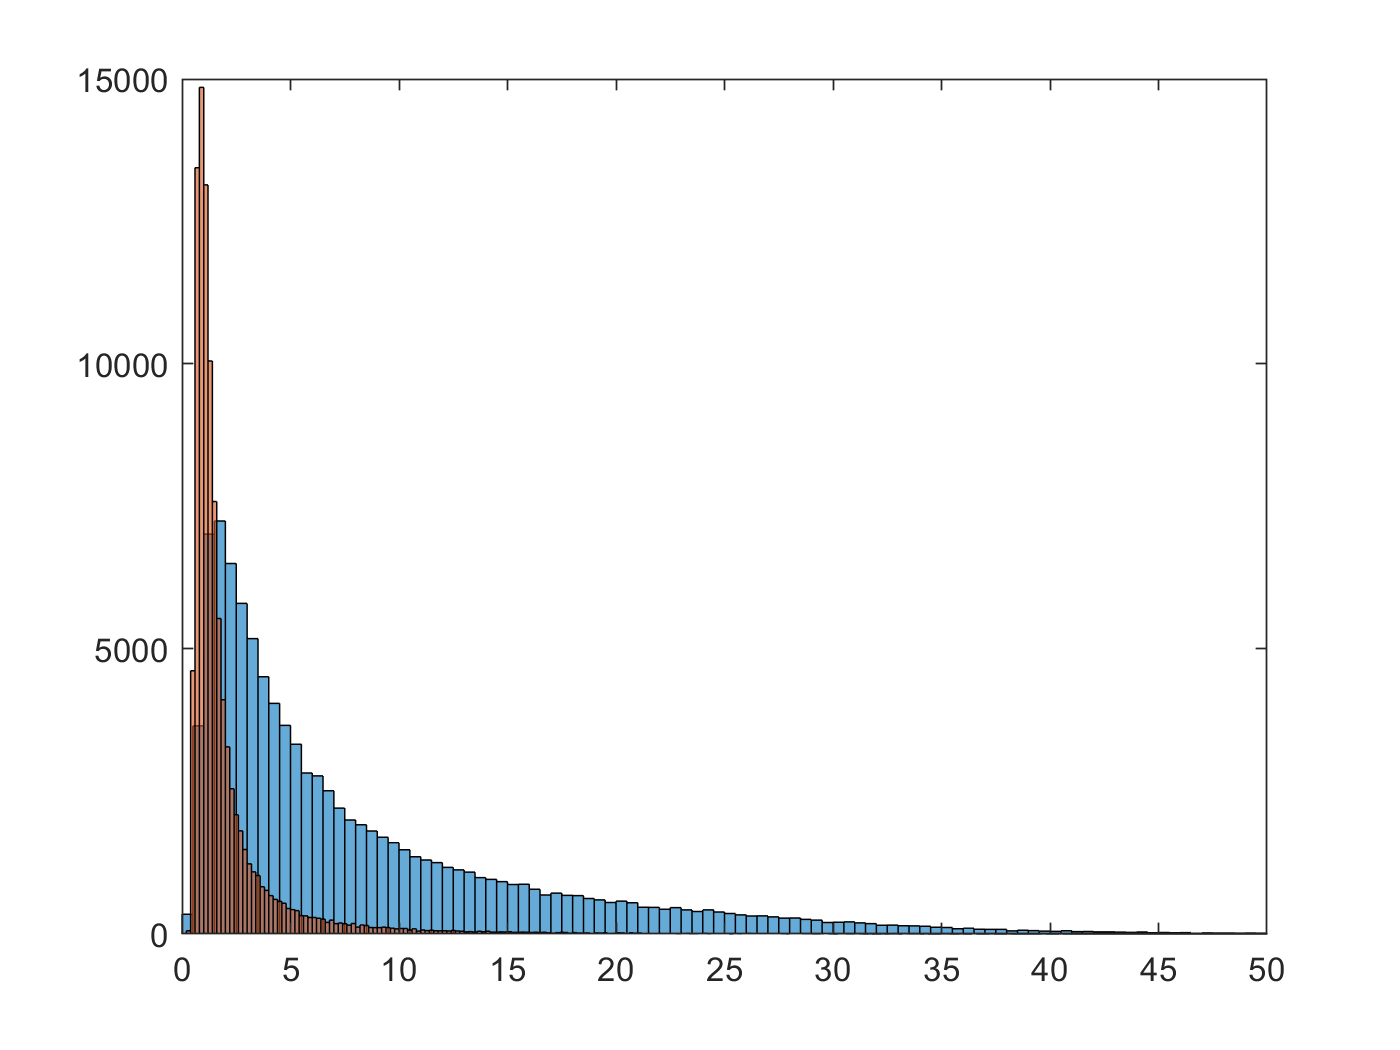

%subplot(2,2,3);
histogram(bgdata1(7,:)), hold on, histogram(signaldata1(7,:)), xlim([0,50]), hold off;

Are distinct.

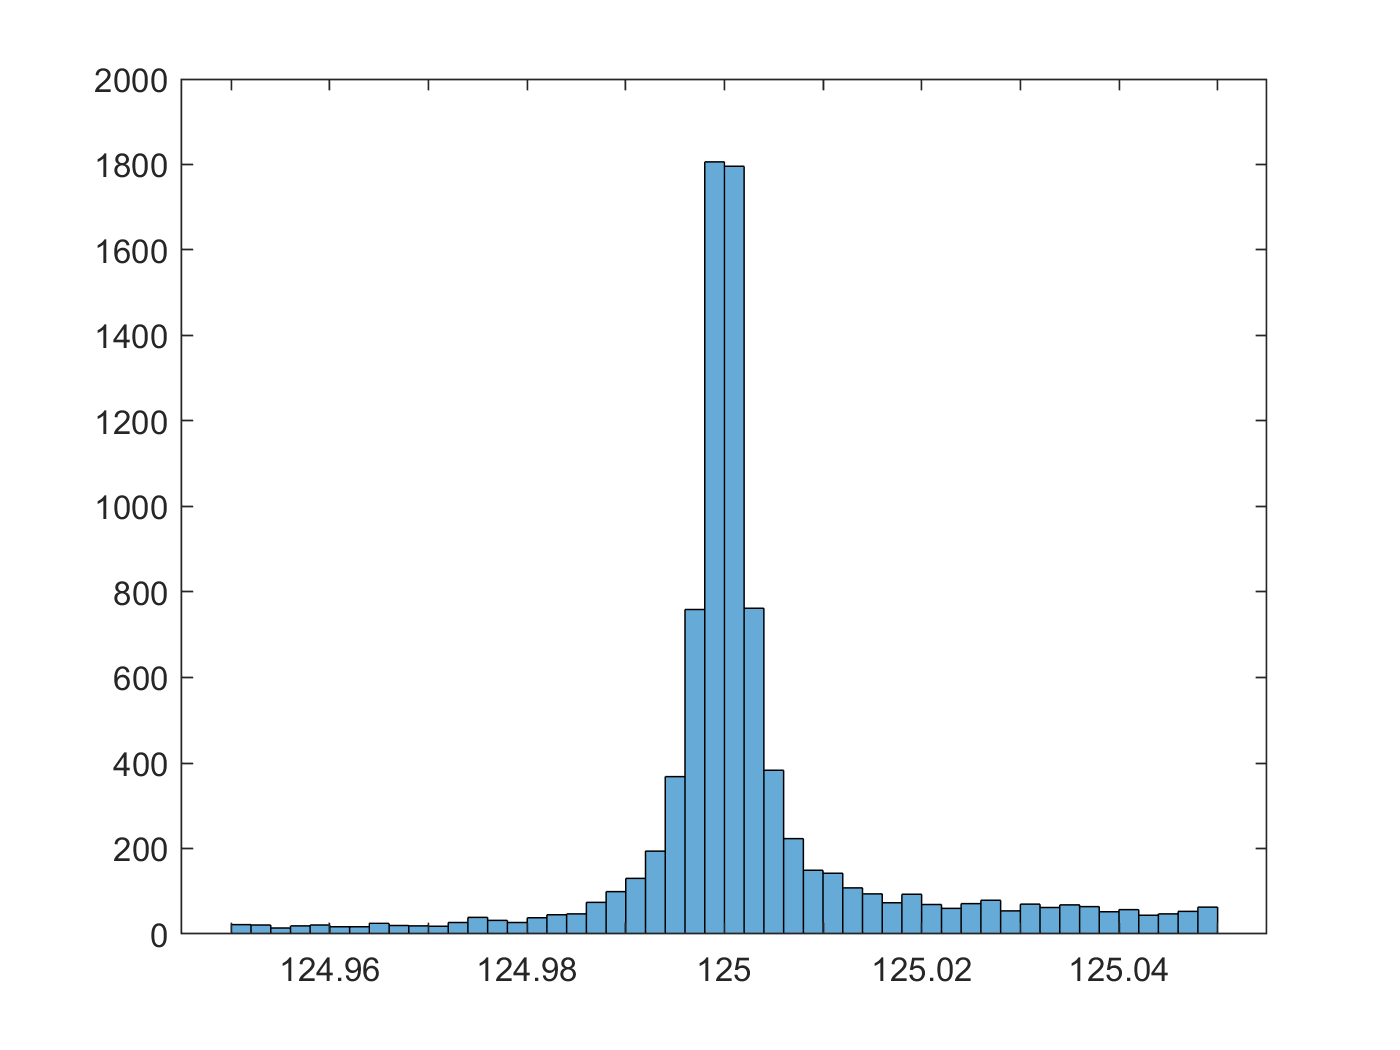

indices = [];
for k = 1:length(signaldata1(4,:))
    if signaldata1(4,k) > 124.95 && signaldata1(4,k) < 125.05
        indices = [indices, k];
    end
end
histogram(signaldata1(4,indices))

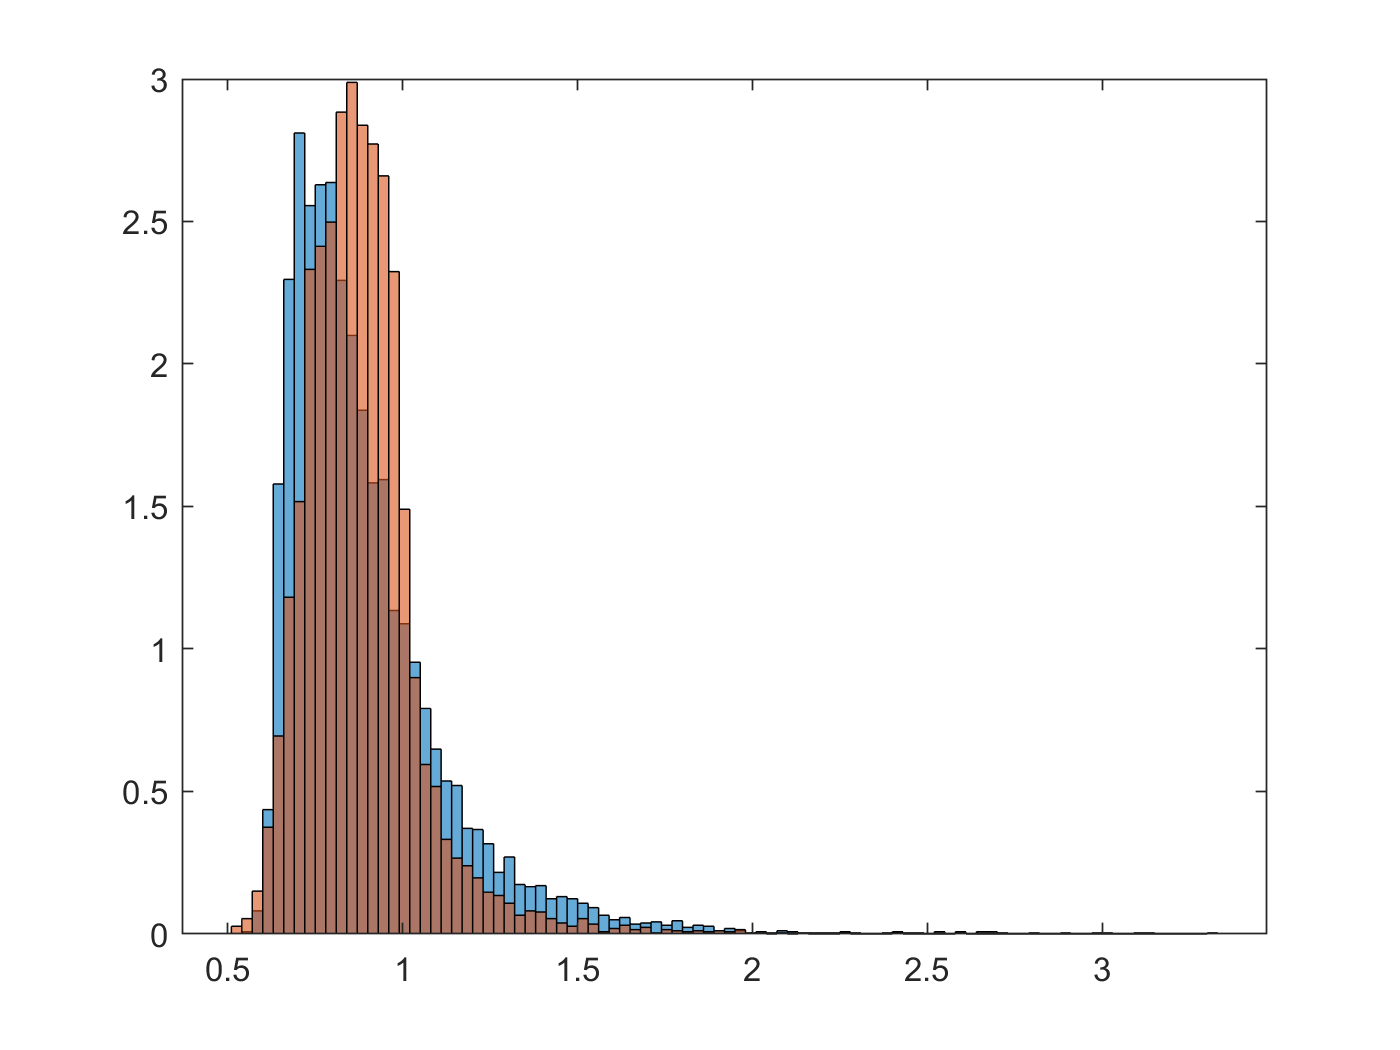

histogram(signaldata1(9,indices),"Normalization","pdf"), hold on, histogram(bgdata1(9,indices),"Normalization","pdf"), hold off;

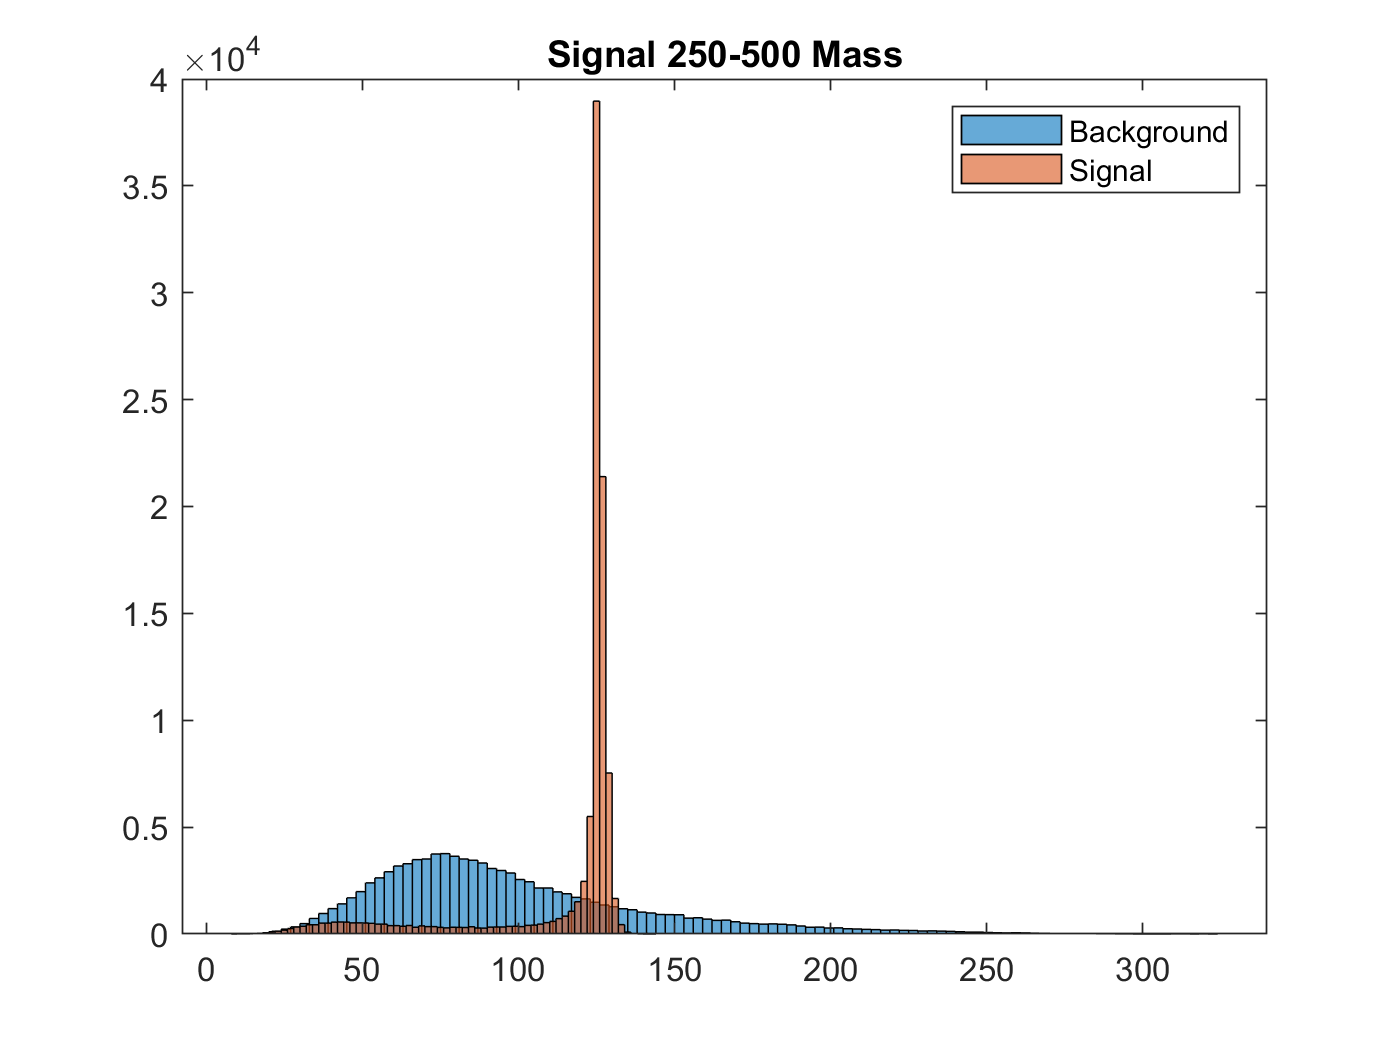

%histogram(signaldata1(4,indices)),hold on,histogram(bgdata1(4,indices)),hold off;

% histogram(bgdata2(4,:));
% hold on;
% histogram(signaldata2(4,:)), title("Signal 250-500 Mass"), legend("Background","Signal");
% hold off;

Major difference in mass distribution between the background and signal data.

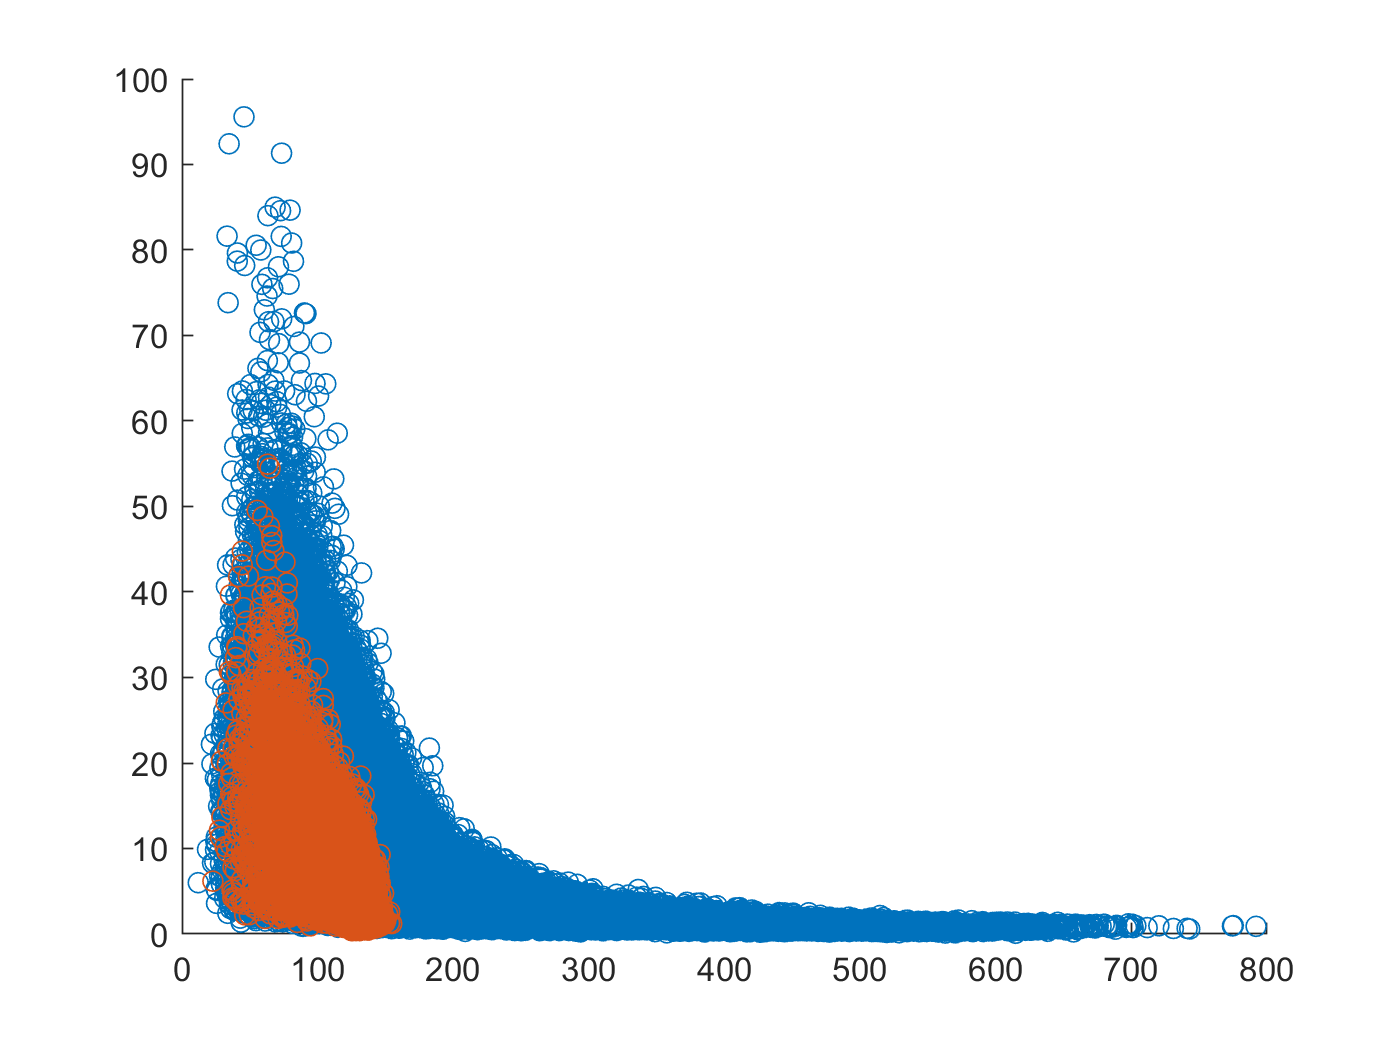

scatter(bgdata1(4,:),bgdata1(7,:)), ylim([0,100]); %xlim([50,200]),
hold on;
scatter(signaldata1(4,:),signaldata1(7,:));
hold off;